# **Magnetometer calibration**

## 1. Magnetometer Data Reading

In this chapter, we will emphasize the IS501 previous steps required to start utilizing it. To achieve this, it is necessary to establish a connection with the magnetometers. Magnetometer communication is achieved through serial data communication.

The driver that we need to install is called "USB-SERIAL CH340." You can install the driver from the following link: 

[CH340 Drivers for Windows, Mac and Linux (gogo.co.nz)](https://sparks.gogo.co.nz/ch340.html).

Subsequently, it is imperative to establish the serial communication.

%disp("Display available Serial Ports:");
%availableSerialPorts = IDSerialComs("available");
%disp(availableSerialPorts);

Then we checked the name USB-SERIAL CH430 and a serial object is necesary to be created.

% for i = 1:size(availableSerialPorts,1)
%     if strcmp('USB-SERIAL CH340',availableSerialPorts{i,1})
%         try
%             s = serialport(availableSerialPorts{i,2},9600);
%             disp('Port connected sucessfully.');
%         catch Err
%             disp(Err.message);
%         end
%     end
% end

Once the magnetometers are connected then start to display and stream data. The data has te following format:

- Mag_xAMag_xBMag_xC

Where 

- Mag_x: Magnetic field in X axis in (nT) whit sign;

- Mag_y: Magnetic field in Y axis in (nT) whit sign;

- Mag_z: Magnetic field in Z axis in (nT) whit sign;

The data was measured with the following code:

%data = read(s,27,"string")

Then the data was split using the sscan function:

%B = sscanf(data,'%fA%fB%fC');
%fprintf('Magnetic Field in X: %.2f nT, in Y: %.2f nT, in Z: %.2f nT',B(1),B(2),B(3))

Close serial port

%delete(s)

## 2. Magnetometer Calibration

### 2.1. Background

A magnetometer is a device capable of detect the magnetic field strength along the X, Y and Z axes. In the **IS501 NMTB **the magnetometer is an important device due to it is used a feedback for the simulation of the earth magnetic field.

Ideally, a three-axis magnetometer measures in the absent of any magnetic interference, magnetometer readings measure the earth's magnetic field [8]. If magnetometer measurements are made in all directions, the measurements should lie on a sphere with a radius of the magnetic field strength [8].

### 2.2. Hard Iron Calibration 

According to [8], noise sources and manufacturing defects degrade a magnetometer's measurement. The most striking of these are hard iron effects. Hard iron effects are stationary interfering magnetic noise sources. Often, these come from other metallic objects on the circuit board with the magnetometer. The hard iron effects shift the origin of the ideal sphere.

### 2.3. Soft Iron Calibration

According to [8], Soft iron effects are more subtle. They arise from objects near the sensor which distort the surrounding magnetic field. These have the effect of stretching and tilting the sphere of ideal measurements. The resulting measurements lie on an ellipsoid.

### 2.4 Correction Technique

In [7] it is mentioned a general process to perform a compass calibration. The process carry out a soft and hard iron compensation wich considers all the magnetic distortions. In [7] it is recomended that the calibration of the compasses must be carried out in its fully operational configuration; all sensors (sensor, electronics and power sources) must be powered on. This will ensure that any current carrying conductors in the vicinity of the sensor (producing hard iron distortion) will also be compensated. Subsequently, users would then have to rotate the entire system (magnetometer) in an environment with a uniform Earth magnetic field. 

In [8] it is explained the $magcal$ matlab function that is used to determine the magnetometer calibration. In [8] the uncalibrated magnetometer data can be modeled as an ellipsoid with equation.


$$(x-b)R(x-b)^T=\beta^2$$


Where: 

$R$ is a 3x3 matrix, $b$ is a 1x3 vector defining the ellipsoid center, $x$ is a 1-3 vector with the uncalibrated magnetometer measurements, and $\beta$ is a scalar indicating the magnetic field strength. 

The $magcal$ function produces correction coefficients that take measurements witch lie on an offset ellipsoid and transform them lo lie on an ideal sphere centered at the origin. The correction data cabe done with equation.


$$m = (x - b) A$$


Here $x$ is a 1-3 array of uncalibrated magnetometer measurements and $m$ is the 1-3 array of corrected magnetometer measurements, which lie on a sphere. The matrix $A$ has a determinant of 1 and is the matrix square root of *R*. Additionally, *A* has the same form as *R* : the identity, a diagonal, or a symmetric matrix. Because these kinds of matrices cannot impart a rotation, the matrix *A* will not rotate the magnetometer data during correction.

### 2.5. Residual Error

The residual error defined by [8] is a quality indicator which is the sum of the distances between the calibrated data and a sphere of radius $\beta$.


$$E=\frac{1}{2\beta^2}\sqrt{\frac{\sum||(x-b)A||^2-\beta^2}{N}}$$


### 2.3. Data Set

The magnetometer calibration was measured and stored in order to perform a previous hard and soft iron calibration. 

## 3. Record magnetic Data

The data recorded was measured in the **IS501 NMTB **in the center of the magnetic chamber. The data was measured with the following program. 

## 4 Analize Data

Read the obtained data.

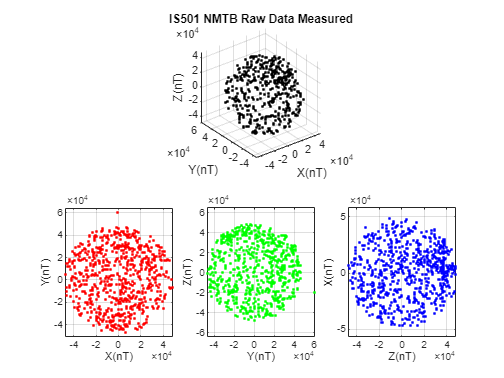

%%% Read data measured
fileName1 = 'rawMagData_Epoch_2023_05_09.mat';
load(fileName1);
rawDataStore1 = rawDataStore;

fileName2 = 'rawMagData_Epoch_2023_07_09.mat';
load(fileName2);
rawDataStore2 = rawDataStore;

%%% Combine data measured two days
rawDataStore = horzcat(rawDataStore1,rawDataStore2);

%%%Load the choosen to environment
figure()
subplot(2,3,1:3)
    plot3(rawDataStore1(1,:),rawDataStore1(2,:),rawDataStore1(3,:),'k.','LineWidth',5); hold on;
    xlabel('X(nT)'); ylabel('Y(nT)'); zlabel('Z(nT)');
    axis equal; grid on; title('IS501 NMTB Raw Data Measured');
subplot(2,3,4)
    h1 = plot(rawDataStore(1,:), rawDataStore(2,:),'r.','LineWidth',5); hold on;
    xlabel('X(nT)'); ylabel('Y(nT)'); axis equal; grid on;
subplot(2,3,5)
    h2 = plot(rawDataStore(2,:), rawDataStore(3,:),'g.','LineWidth',5); hold on;
    xlabel('Y(nT)'); ylabel('Z(nT)'); axis equal; grid on;    
subplot(2,3,6)
    h3 = plot(rawDataStore(3,:), rawDataStore(1,:),'b.','LineWidth',5); hold on;
    xlabel('Z(nT)'); ylabel('X(nT)'); axis equal; grid on;  

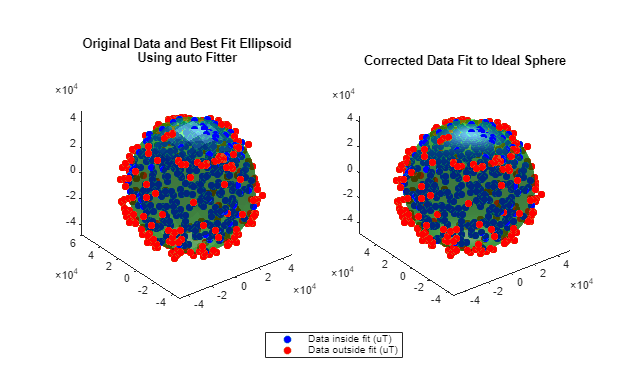

%%% magnetometer data, simply call the function as: 
[A,b,expMFS]  = magcal(rawDataStore','auto');
xCorrected = (rawDataStore'-b)*A;


%%% Plot the original and corrected data. Show the ellipsoid that best fits
%%% the original data. Show the sphere on which the corrected data should
%%% lie.
de = HelperDrawEllipsoid;
de.plotCalibrated(A,b,expMFS,rawDataStore',xCorrected,'auto');

% The |magcal| function uses a variety of solvers to minimize the residual
% error. The residual error is the sum of the distances between the
% calibrated data and a sphere of radius |expMFS|.
%
% $$E = \frac{1}{2 \beta^2}\sqrt{ \frac{\sum  ||(x-b)A||^2 - \beta^2}{N} }$$
%
N = size(xCorrected,2);
r = sum(xCorrected.^2,2) - expMFS.^2;
E = sqrt(r.'*r./N)./(2*expMFS.^2);
fprintf('Residual error in corrected data : %.2f\n\n',E);

Residual error in corrected data : 2.42



The calculated parameters made for calibration are:

disp(A)

    1.0503   -0.0107   -0.0014
   -0.0107    0.9895    0.0073
   -0.0014    0.0073    0.9624



disp(b)

   1.0e+03 *

   -0.4991   -0.0897    2.6206



function devices = IDSerialComs(options)
% IDSerialComs identifies Serial COM devices on Windows systems by friendly name
% Searches the Windows registry for serial hardware info and returns devices,
% a cell array where the first column holds the name of the device and the
% second column holds the COM number. Devices returns empty if nothing is found.
% Copyright (c) 2014, Benjamin W. Avants
% All rights reserved.

devices = [];

%%% Get the name of the available serial ports
availableSerialPorts = serialportlist(options);
if isempty(availableSerialPorts)
    disp('No Serial COMS available')
    return;
end

%%% Get the friendly name
key = 'HKEY_LOCAL_MACHINE\SYSTEM\CurrentControlSet\Enum\USB\';
[~, vals] = dos(['REG QUERY ' key ' /s /f "FriendlyName" /t "REG_SZ"']);
if ischar(vals) && strcmp('ERROR',vals(1:5))
    disp('Error: IDSerialComs - No Enumerated USB registry entry')
    return;
end
vals = textscan(vals,'%s','delimiter','\t');
vals = cat(1,vals{:});
out = 0;
for i = 1:numel(vals)
    if strcmp(vals{i}(1:min(12,end)),'FriendlyName')
        if ~iscell(out)
            out = vals(i);
        else
            out{end+1} = vals{i}; %#ok<AGROW> Loop size is always small
        end
    end
end

for i = 1:numel(availableSerialPorts)
    match = strfind(out,availableSerialPorts{i});
    ind = 0;
    for j = 1:numel(match)
        if ~isempty(match{j})
            ind = j;
        end
    end
    if ind ~= 0
        com = str2double(erase(availableSerialPorts{i},'COM'));
        if com > 9
            length = 8;
        else
            length = 7;
        end
        devices{i,1} = out{ind}(27:end-length); %#ok<AGROW>
        devices{i,2} = availableSerialPorts{i}; %#ok<AGROW> Loop size is always small
    end
end
end